clc % clear command window
clear % clear MATLAB workspace

**Set up robot control system**

% create arduino ref-objects
    [robotArduino, rawRangeIn, blinkLED]= SETUPARDUINO('COM13');
    
% Turn on board LED on and off to signal program has started
    Blink(robotArduino,blinkLED,3);
    disp('Warning! Position Servo Active! ');

Warning! Position Servo Active! 


% Configuration test loop to collect n points
    nTests = input(['Enter number of range test position, '...
        'followed by enter: ']);
  clc
    
% Create a variable to hold experimental position data
    positionData = zeros(nTests,2);
    
r = rateControl(0.25);
reset(r);

**Run Robot Control Loop**

controlFlag = 1;                    % create a loop control
while (controlFlag < nTests+1)      % loop till ntests data captured
    
    for i = 1:10
        rangeData(i) = SENSE(robotArduino, rawRangeIn);
    end
    rangeData = mean(rangeData)
    
    THINK(); % compute what the robot should do next    
    ACT(); % command robot actuators
    
    % store experimental commanded versus actual data
    positionData(controlFlag,1) = input('Enter actual distance(cm): ');
    gtest = input('move Sonar to new range, type G and then hit Enter','s')
    positionData(controlFlag,2) = rangeData;
    Blink(robotArduino, blinkLED, 1);
    waitfor(r);                     % wait for code cycle to complete
    controlFlag = controlFlag + 1;  %increment loop
end

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.5714

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.6227

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.5269

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.4956

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.4941

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.4775

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.4575

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.4326

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.4350

gtest = 'G'

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


rangeData = 0.4091

gtest = 'G'

**Sensor testing (print voltage repeatedly)**

% entries = 30;
% % pause_time = 0.1;
% t = linspace(0,entries*pause_time,entries);
% distance_arr = [];
% for i = 1:entries    
%     for j = 1:20
%         voltage(j) = readVoltage(robotArduino, rawRangeIn);
%     end
%         avg_voltage = mean(voltage);
% 
%     distance_arr(i) = voltage_to_distance(avg_voltage);
%     pause(pause_time);
% end

% t
% distance_arr
% plot(t, distance_arr, 'o')
% ylim([0, 1000])
% title("Object in Front")
% xlabel('Time/s')
% ylabel('Distance/cm')

**Mission data processing**

For many robot appliaction, you will need to post-process the data collected after the mission. Here we will plot the desied versus actual motor positions.

%Plot and store commanded position data vs. actual position
xData = positionData(:,1) + 21.59

xData =    21.5900
   22.5900
   23.5900
   24.5900
   25.5900
   26.5900
   27.5900
   28.5900
   29.5900
   30.5900


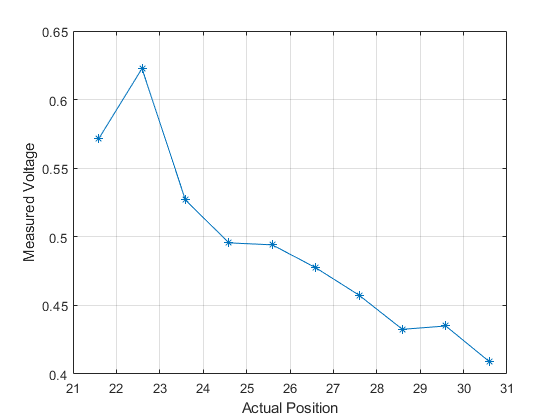

figure
plot(xData, positionData(:,2), '-*')
hold on
xlabel('Actual Position')
ylabel('Measured Voltage')
grid

%Linear Fit
x = xData;
y = positionData(:,2);
c = polyfit(x, y, 1)

c =    -0.0205    1.0262


xline = 21:1:30

xline =     21    22    23    24    25    26    27    28    29    30


yline = c(1)*x + c(2)

yline =     0.5843
    0.5639
    0.5434
    0.5229
    0.5025
    0.4820
    0.4615
    0.4411
    0.4206
    0.4001


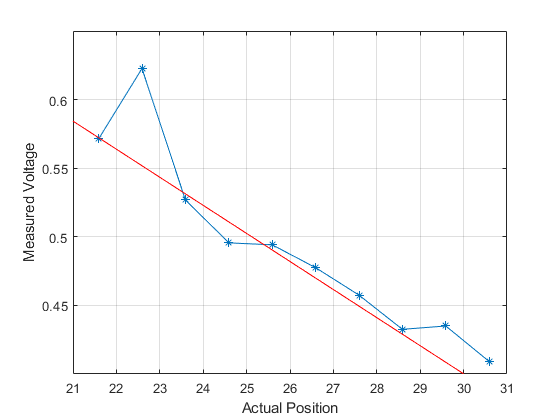

plot(xline,yline,'r')
hold off

**Filtering**

%collecting the data

t =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


for i = 1:20
    rangeDataOvertime(i)  = SENSE(robotArduino, rawRangeIn);
    pause(0.5)
end

Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense
Sense


Error using plot
Vectors must be the same length.

%Adding moving pass filter
% copying data into another y matrix
y = rangeDataOvertime

y =     0.6403    0.6207    0.5670    0.5670    0.5670    0.6207    0.5670    0.5767    0.5181    0.5670    0.6109    0.6207    0.5670    0.5670    0.5816    0.5670    0.5718    0.5718    0.5670    0.5670


% finding the average point
avg = mean(rangeDataOvertime)

avg = 0.5802

% filtering the data so that outlier points are removed
for i = 1:length(y)
    if (y(i) > avg + 0.02 || y(i) < avg - 0.02)
        y(i) = avg;
    end
end
% defining time
t = linspace(0,0.5*(length(rangeDataOvertime) - 1),length(rangeDataOvertime));

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000


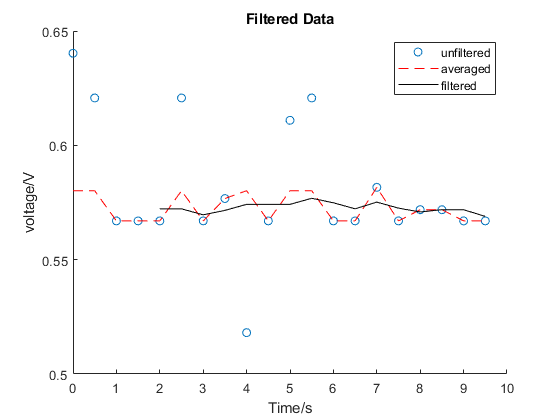

% adding a moving pass filter
windowSize = 5;
b = (1/windowSize) * ones(1,windowSize);
a =1;
moving_filtered = filter(b,a,y);
%plotting the raw data, the moving pass filter and the averaged data
figure
hold on
plot(t,rangeDataOvertime,'o')
plot(t,y,'r--')
plot(t(windowSize:end),moving_filtered(windowSize:end),'k')
hold off
xlabel('Time/s')
ylabel('voltage/V')
title('Filtered Data')
legend('unfiltered','averaged','filtered')

**Finding target and hole**

entries = 30;
pause_time = 0.2;
% collecting points and averaging them
t = linspace(0,entries*pause_time,entries);
for i = 1:entries    
    for j = 1:20
        voltage(j) = readVoltage(robotArduino, rawRangeIn);
    end
    avg_voltage = mean(voltage);
    % finding the distance for each point
    distance(i) = volt2dist(avg_voltage);
    pause(pause_time);
end
plot(t,distance)
xlabel('Time/s')
ylabel('Distance/cm')
title('Finding hole and target')


function distance = volt2dist(voltage)
distance = (voltage - 1.062)/(-0.0295)
end

**Clean shut down**

finally, with most embedded robot controllers, it's good practice to put all actuators into a safe postion and then release all control objects and shut down all communication paths. This keeps systems from jamming when you want to run again.

% Stop program and clean up the connection to Arduino when no longer needed
clc
disp('Arduino program has ended');

Arduino program has ended



clear robotArduino
beep           % play system sound to let user know program is ended

**Robot Functions**

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot
% controller. It requires which COM Port your Arduino is attached to as its
% input and returns an Arduino object called robotArduino. 

% Creates a global arduino object so that it can be used in functions 
% a = arduino('setToYourComNumber','Uno',Libraries','Servo');
    robotArduino = arduino(COMPORT, 'Uno','Libraries','Servo');

% configure pin 13 as a digital-out LED
    blinkLED = 'D13';
    configurePin(robotArduino,blinkLED,'DigitalOutput');

% configure A0 pin as an analog input
    rawRangeIn = 'A3';
    configurePin(robotArduino, rawRangeIn, 'AnalogInput')
end

function [] = Blink(a,LED,n)
% Blink toggles Arduino a LED on and off to indicate program running input
% n is number of blinks
% no output is returned
    for bIndex = 1:n
        writeDigitalPin(a,LED,0);
        pause(0.2);
        writeDigitalPin(a,LED,1);
        pause(0.2);
    end
end

**Sense Function** (store all Sense related Local functions)

function rangeData = SENSE(robotArduino, rawRangeIn)
disp('Sense');
rangeData = readVoltage(robotArduino, rawRangeIn);
end

**Think Function **(store all Think related Local functions)

function THINK()
    % null function, not much thinking to do here
end

% function distance = voltage_to_distance(voltage)
%     distance = (voltage + 0.021092)/ 0.0047884;
% %     Equation is y = 0.0047884*x + 0.1465
% % Equation is y = 0.0047884*x + -0.021092
% end

**Act Function **(store all Act related Local functions)

function ACT()
% null function    
end
